# 802.11a/g decode

## Read the file

clear
clc

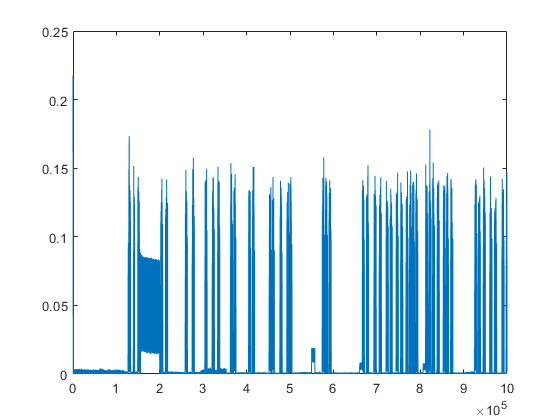

%%%% Read from raw sample file
raw_data = read_complex_binary('../rawSample/exp2/l_1_1.dat',1e6);
investigated_signal = raw_data;
plot(abs(investigated_signal))

bbw = comm.BasebandFileWriter('baseband_data.bb',20e6,2.412e9);
bbw.Metadata = struct('Date',date);
bbw(investigated_signal)
info(bbw)

ans = struct with fields:
             Filename: 'C:\Users\Lihao\OneDrive - The Chinese University of Hong Kong\Research Topic\Parallel Networking\Simulation\USRP\WLAN_decoder\Wireless Analyszer\baseband_data.bb'
      SamplesPerFrame: 1000000
          NumChannels: 1
             DataType: 'double'
    NumSamplesWritten: 1000000


release(bbw);

### Import a Captured Waveform from a File

This section loads I/Q data from an existing binary file using [comm.BasebandFileReader](docid:comm_ref#bvbbo5v-1). The baseband file format includes the sample rate and the number of channels in the captured waveform. Alternately you can load the waveform in a MAT-file format.

% Configure the analysis source
    BBR = comm.BasebandFileReader('baseband_data.bb'); % Create a baseband file reader object
    chanBW = 'CBW20'; % Channel bandwidth of all packets within the waveform
    bbrInfo = info(BBR);
    BBR.SamplesPerFrame = bbrInfo.NumSamplesInData; % Number of sample in the waveform
    rxWaveform = BBR();  % Load the I&Q sample from a binary file
    sr = BBR.SampleRate; % Sampling rate of the input signal
    release(BBR);

To view an example that recovers beacon packets from a baseband file see the [802.11 OFDM Beacon Receiver with Captured Data](docid:wlan_ug#example-NonHTBeaconReceiverExample) example.

## Signal Recovery and Analysis

This section detects, analyzes, and displays a summary of the detected packets. All packets in the waveform must have the specified channel bandwidth, `chanBW.`

% Create a WaveformAnalyzer object to parse and analyze the packet within a waveform
analyzer = WaveformAnalyzer;
process(analyzer,rxWaveform,chanBW,sr);

% Display the summary of the detected packets
detectionSummary(analyzer);

                                                                           Summary of the Detected Packets



detSummary = 97×9 table
    Number     Format          PHY Status         Power (dBm)     CFO (Hz)     Offset (samples)    MAC Contents    RMS EVM (dB)    Max EVM (dB)
    ______    ________    ____________________    ___________    __________    ________________    ____________    ____________    ____________

       1      "Non-HT"    "Success"                    4.8           -20901       1.2684e+05        "Unknown"        0.74814          17.572   
       2      "HT-MF"     "HT-SIG CRC fail"           0.17          -1980.7       1.3788e+05        "Unknown"            NaN             NaN   
       3      "Non-HT"    "Success"                   2.86           -20190       1.5341e+05 

Use the `pktNum` variable to display the MAC and PHY analysis for a selected packet.

pktNum = 4 ;

% Display the MAC information of the selected packet
macSummary(analyzer,pktNum);

 
                      Recovered MPDU Summary of Packet 4

       Address1          Address2       MPDU Decode Status    MAC Frame Type
    ______________    ______________    __________________    ______________

    "207C8F9B56E7"    "00CA05009593"         Success            "QoS Data"  



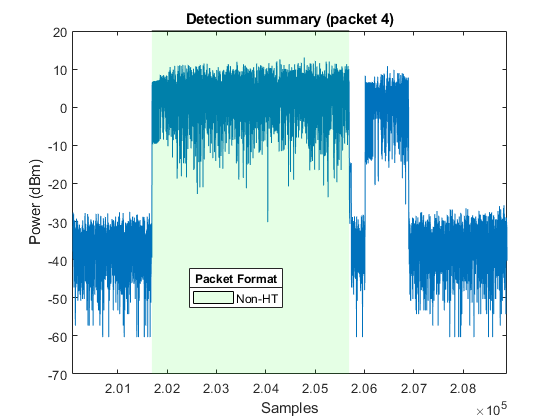

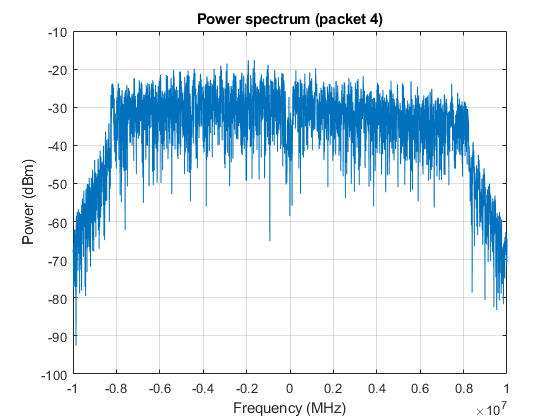

% Display the time samples and the spectrum of the detected packet
plotWaveform(analyzer,pktNum)

% Display the packet field information of the selected packet
fieldSummary(analyzer,pktNum);

 
                                           Field Summary of Packet 4 (Non-HT)

    Field Name    Modulation    MCS    Num Symbols    Parity Check    Power (dBm)    RMS EVM (dB)    Max EVM (dB)
    __________    __________    ___    ___________    ____________    ___________    ____________    ____________

      L-STF         BPSK                    2                            4.52                                    
      L-LTF         BPSK                    2                            4.70                                    
      L-SIG         BPSK                    1             Pass           4.41          -32.01          -26.04    
      Data          BPSK         0         45              

% Display signaling field information of the selected packet
signalingSummary(analyzer,pktNum);

 
 L-SIG Field and Bandwidth Signaling Summary

            Property              Value
   ___________________________    _____

    L-SIG Length                   132  
    L-SIG Rate                     0xB  
    Signaled Channel Bandwidth     CBW40
    Dynamic Bandwidth Operation    True 


% Display the RU information
ruSummary(analyzer,pktNum);
% Display the user information
userSummary(analyzer,pktNum);

 
          User Information of Packet 4 (Non-HT)

    MCS    Modulation    Code Rate    Channel Coding
    ___    __________    _________    ______________

     0       "BPSK"        "1/2"          "BCC"     




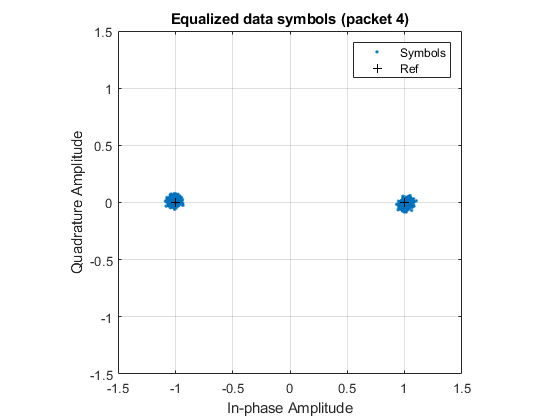

% Display EVM per spatial streams for all user
userEVM(analyzer,pktNum);
% Plot constellation for all users
plotConstellation(analyzer,pktNum);

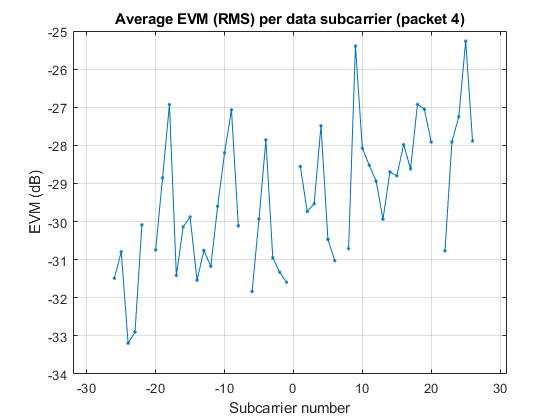

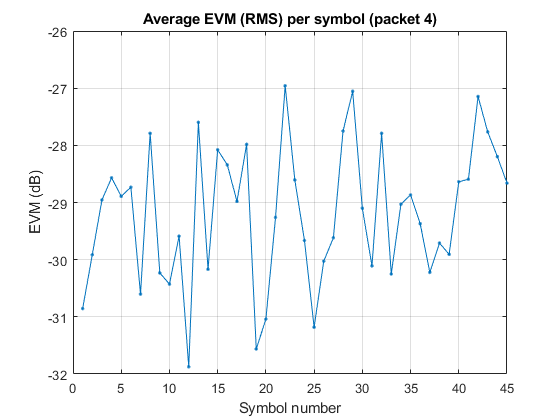

% Plot EVM
plotEVM(analyzer,pktNum);

## Further Exploration

The `WaveformAnalyzer` provides properties to control the pilot tracking, equalization, DC blocking, and packet detection algorithms that can be tweaked to improve packet detection and analysis performance.

**False packet detections**

False packet detections are detected packets that you do not believe are actual packets. Evaluating the time domain waveform of the packet is one way to determine if the detected packet is legitimate. If there is a significant number of false detections present these techniques may help reduce them:

- Enable the `EnergyDetection` property and set the `EnergyDetectionThreshold` property to a suitable value given the noise floor of the capture device. When enabled, `EnergyDetection` only detects packets with a power exceeding `EnergyDetectionThreshold` during the preamble.

- Increase the `LLTFSNRDetectionThreshold `and` PacketDetectionThreshold `properties to discard packets with a low measured SNR during detection.

**Missed packet detections**

Missed packet detections are packets that you believe are in the waveform but have not been detected.

- One possible reason a packet detection may have been missed is if a false detection occurred earlier in the waveform, but the L-SIG check passed, causing samples to be skipped. To search within possible false detections, enable the `SearchWithinUnsupportedPacket` property.

- Alternatively try decreasing the `PacketDetectionThreshold` property to detect packet with low SNR during detection.

For detail on 802.11ax and 802.11ac signal recovery and processing, see the [Recovery Procedure for an 802.11ax Packet](docid:wlan_ug#example-HESignalRecoveryExample) and [Recovery Procedure for an 802.11ac Packet](docid:wlan_ug#example-VHTSignalRecoveryExample) examples.

## Selected Bibliography

- IEEE Std 802.11™ - 2020 IEEE Standard for Information technology - Telecommunications and information exchange between systems - Local and metropolitan area networks - Specific requirements - Part 11: Wireless LAN Medium Access Control (MAC) and Physical Layer (PHY) Specifications.

- IEEE P802.11ax™/D4.1 Draft Standard for Information technology - Telecommunications and information exchange between systems - Local and metropolitan area networks - Specific requirements - Part 11: Wireless LAN Medium Access Control (MAC) and Physical Layer (PHY) Specifications - Amendment 6: Enhancements for High Efficiency WLAN.

*Copyright 2019-2021 The MathWorks, Inc.*